# Tutorial04 Simulating and Imaging Randomly Diffusing Molecules

#### Notes

Note. Save all my code. They will be reused and build on each other.

Objective: To be more famiiar with Matrix multiplications through a variation of a random walk.

2. Simulating a Random Walk in 1D

1.. Initialize two matrices

% Parameters
L = 500

L = 500

n_particle = 500

n_particle = 500

n_kicks = 10000

n_kicks = 10000


f = zeros(n_kicks, n_particle);
x = zeros(n_kicks, n_particle);

2.. Assign the initial particle positions in f(1, :) such that the n_p particles are uniformly disributed across the Universe.

% Initially did
% f(1,:) = length*rand(1, n_particle)

% After reaching step 5, for convenience, decided to refer to the solution.
f(1,:) = randperm(L)

f =    227   451   401   402    84   268   373   411   295    74    75   100   353   191   294   442   374   145   171   478    22   456   113   169   397   337   496   112   460   251   323   386   310   263    79   360   189   350    12   260   235   461    36   269   372   291    91   273    40    19
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

3.. Store displacement of each kick.

Received help from solution doc.

% Assign kicks at each time step.
f(2:end,:) = randn(n_kicks-1, n_particle)

f =   227.0000  451.0000  401.0000  402.0000   84.0000  268.0000  373.0000  411.0000  295.0000   74.0000   75.0000  100.0000  353.0000  191.0000  294.0000  442.0000  374.0000  145.0000  171.0000  478.0000   22.0000  456.0000  113.0000  169.0000  397.0000  337.0000  496.0000  112.0000  460.0000  251.0000  323.0000  386.0000  310.0000  263.0000   79.0000  360.0000  189.0000  350.0000   12.0000  260.0000  235.0000  461.0000   36.0000  269.0000  372.0000  291.0000   91.0000  273.0000   40.0000   19.0000
   -0.5725   -0.5832    2.2485    0.8702   -0.8632   -0.8413    1.3719   -1.4793   -0.6797   -1.8816   -0.3419    1.3082   -0.5473    0.5958    0.0943   -0.1609    1.7581    0.6113   -0.9779   -0.2736    2.1602   -0.7864   -0.8316    1.9288   -0.8314    0.4490   -0.1382    1.1789    0.9228    0.0586    1.7805    0.0694    1.6347   -1.3298   -0.8392   -0.1334   -0.2568   -0.7797   -1.4631    0.7922   -0.5913    0.6988    1.0831   -0.2270    1.1419    0.3848    0.5134    0.6629   -0.3795    0

Note. Difference between **rand** and **randn**.

**rand**: uniformly distributed random numbers. Returns random #s between 0 and 1 from uniform distribution.

**randn**: normally(Gaussian) distributed random numbers. Returns random #s of mean 0 and variance 1.

4.. Assign x to the particle trajectories. Use **cumsum** and mod.

% help cumsum
% stepx = cumsum(-1+2*stepx)
x = cumsum(f)

x =   227.0000  451.0000  401.0000  402.0000   84.0000  268.0000  373.0000  411.0000  295.0000   74.0000   75.0000  100.0000  353.0000  191.0000  294.0000  442.0000  374.0000  145.0000  171.0000  478.0000   22.0000  456.0000  113.0000  169.0000  397.0000  337.0000  496.0000  112.0000  460.0000  251.0000  323.0000  386.0000  310.0000  263.0000   79.0000  360.0000  189.0000  350.0000   12.0000  260.0000  235.0000  461.0000   36.0000  269.0000  372.0000  291.0000   91.0000  273.0000   40.0000   19.0000
  226.4275  450.4168  403.2485  402.8702   83.1368  267.1587  374.3719  409.5207  294.3203   72.1184   74.6581  101.3082  352.4527  191.5958  294.0943  441.8391  375.7581  145.6113  170.0221  477.7264   24.1602  455.2136  112.1684  170.9288  396.1686  337.4490  495.8618  113.1789  460.9228  251.0586  324.7805  386.0694  311.6347  261.6702   78.1608  359.8666  188.7432  349.2203   10.5369  260.7922  234.4087  461.6988   37.0831  268.7730  373.1419  291.3848   91.5134  273.6629   39.6205   19

x = mod(x, 500)

x =   227.0000  451.0000  401.0000  402.0000   84.0000  268.0000  373.0000  411.0000  295.0000   74.0000   75.0000  100.0000  353.0000  191.0000  294.0000  442.0000  374.0000  145.0000  171.0000  478.0000   22.0000  456.0000  113.0000  169.0000  397.0000  337.0000  496.0000  112.0000  460.0000  251.0000  323.0000  386.0000  310.0000  263.0000   79.0000  360.0000  189.0000  350.0000   12.0000  260.0000  235.0000  461.0000   36.0000  269.0000  372.0000  291.0000   91.0000  273.0000   40.0000   19.0000
  226.4275  450.4168  403.2485  402.8702   83.1368  267.1587  374.3719  409.5207  294.3203   72.1184   74.6581  101.3082  352.4527  191.5958  294.0943  441.8391  375.7581  145.6113  170.0221  477.7264   24.1602  455.2136  112.1684  170.9288  396.1686  337.4490  495.8618  113.1789  460.9228  251.0586  324.7805  386.0694  311.6347  261.6702   78.1608  359.8666  188.7432  349.2203   10.5369  260.7922  234.4087  461.6988   37.0831  268.7730  373.1419  291.3848   91.5134  273.6629   39.6205   19

**cumsum**: cumulative sum of elements. Check documentation how it works for a matrix.

Sample Code

`Cumsum of each column`

`A = [1 4 7; 2 5 8; 3 6 9]`

`A = `*3×3*

`     1     4     7`

`     2     5     8`

`     3     6     9`

`B = cumsum(A)`

`B = ``3×3`

`     1     4     7`

`     3     9    15`

`     6    15    24`

`Cumsum of each row`

`A = [1 3 5; 2 4 6]`

`A = ``2×3`

`     1     3     5`

`     2     4     6`

`B = cumsum(A,2)`

`B = ``2×3`

`     1     4     9`

`     2     6    12`

**mod**: Takes mod. 

Sample code.

q = [0:10] 

mod(q,5)

mod(q,4)

Q = [0:10;0:10;0:10] 

mod(Q,5) 

mod(Q,2)

Here, mod is used to ensure the particles stay in the universe.

5.. Visualizing particle trajectories by creating an *image*.

I(x,t). corresponds to the # of particles at location x at time t. 

Image: a matrix that represents the grid of pixels, whose entires contain some info about those pixels - here, it's intensity. c.f. The higher the count of a pixel, the brighter it'll be.

% first, use ceiling to discretize x.
x = ceil(x)

x =    227   451   401   402    84   268   373   411   295    74    75   100   353   191   294   442   374   145   171   478    22   456   113   169   397   337   496   112   460   251   323   386   310   263    79   360   189   350    12   260   235   461    36   269   372   291    91   273    40    19
   227   451   404   403    84   268   375   410   295    73    75   102   353   192   295   442   376   146   171   478    25   456   113   171   397   338   496   114   461   252   325   387   312   262    79   360   189   350    11   261   235   462    38   269   374   292    92   274    40    20
   224   452   404   404    84   267   375   410   295    74    75   101   351   192   295   442   376   144   169   477    26   456   113   172   398   338   496   114   461   252   325   386   312   261    79   360   189   348     9   260   233   462    35   268   372   293    91   275    39    18
   226   451   405   404    85   269   377   408   295    73    75   101   352   191   295   


% create image to store result.
% initialize image
I = zeros(L, n_kicks)

I =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   


% for each number from 1 to 500, count the occurence and store in the matrix.
for n = 1:n_kicks
    location_ranges = 1:500;
    [counts, ind] = histc(x(n, :), location_ranges);
    % transpose(counts)
    I(:, n) = transpose(counts);  % can use " counts.' "
end


% Below is an alternative from sample solution.
% Create the image I(x,t) by counting the # of particles at each time
% at all positions using hist.
%for n = 1:n_kicks  % correct
%    I(:, n) = hist(x(n, :), n_particle);
%end

I

I =      1     2     1     2     4     1     1     2     2     0     0     1     0     1     0     1     0     1     2     1     1     1     1     1     0     1     2     1     2     2     3     0     2     1     1     1     3     3     1     1     2     3     1     0     0     1     3     2     2     1
     1     0     2     3     1     1     2     0     0     1     0     0     1     0     1     1     0     2     2     0     3     1     2     0     2     1     1     2     2     1     1     2     1     2     2     1     1     1     3     2     0     0     0     0     2     0     0     1     1     1
     1     0     0     1     1     3     0     1     1     2     1     1     2     2     1     1     3     1     0     2     0     0     0     0     0     1     1     1     1     1     0     2     2     0     0     1     0     1     1     1     3     1     1     2     1     1     2     1     2     0
     1     1     1     1     0     0     2     3     2     1     3     0     0     1     1   

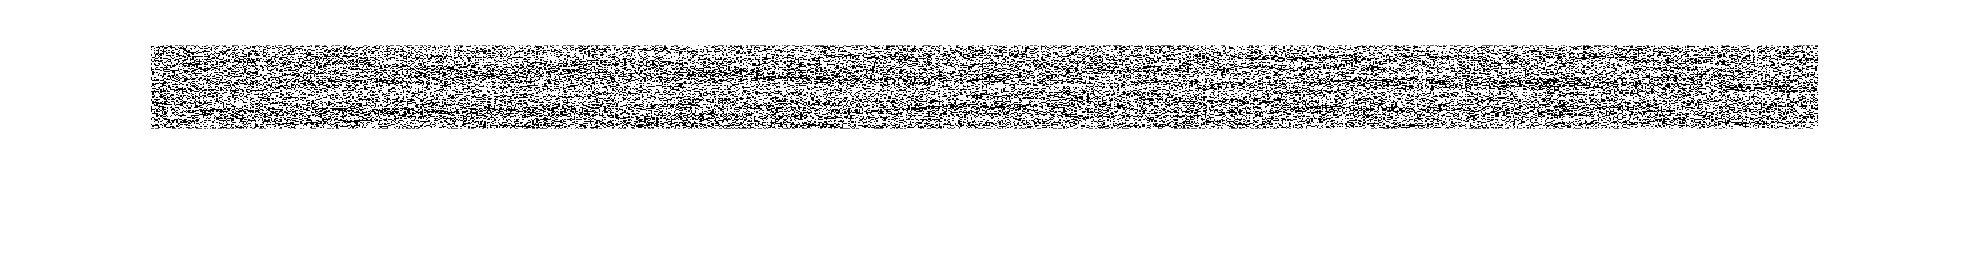

%groupcounts(x)

imshow(I)

Choosing subsection of the matrix and showing it.

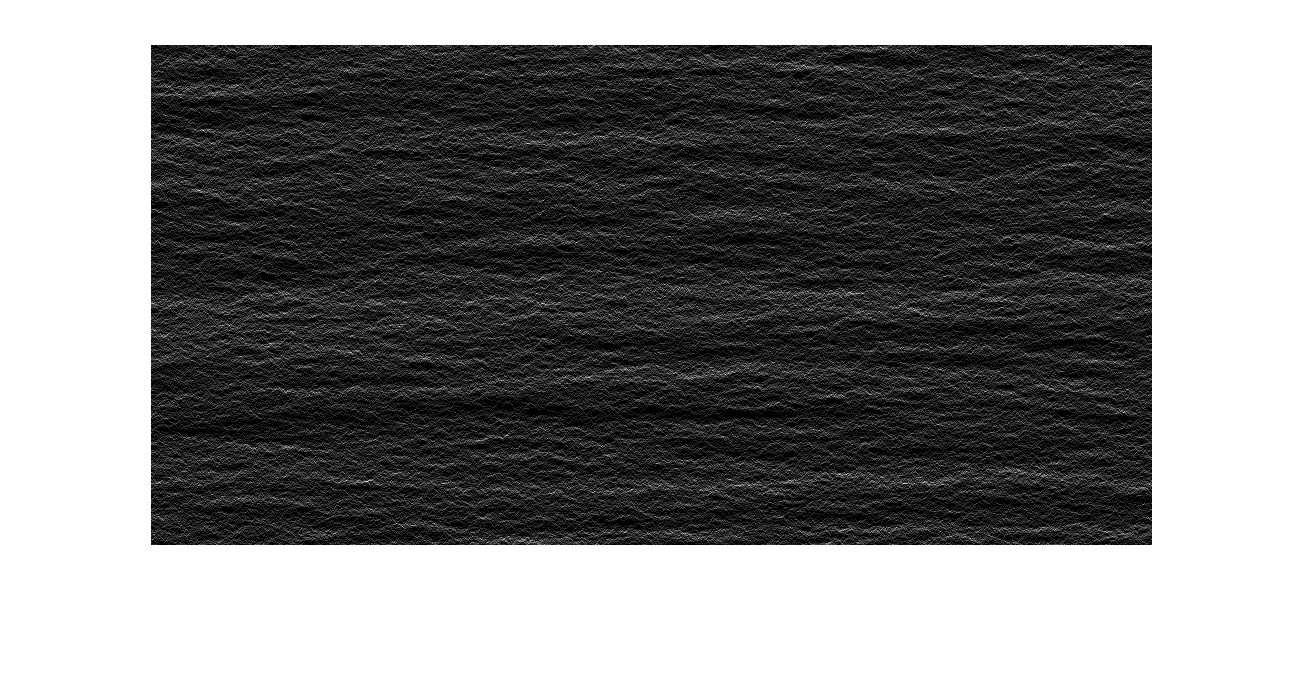

%figure
%I_section = I(:, 4500:5500,[])
% Correction comment: my initial range was 3:950, which was too wide.
imshow(I(:,4500:5500),[])

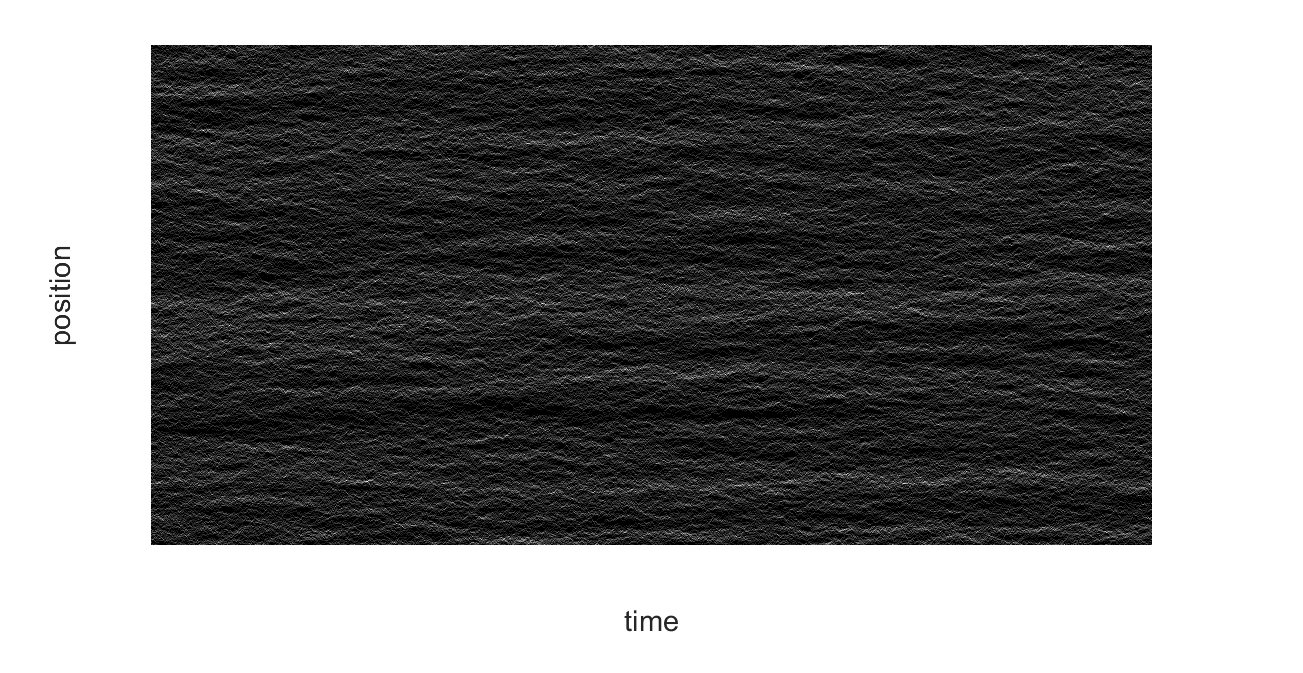


figure % create figure window
imshow(I(:,4500:5500),[]);
xlabel(['time']),ylabel(['position']) 

6.. Calculate the variance in positions sampled by each particle.

% var_particles = var(transpose(I))

% Correction:
variance_x = zeros(1, n_particle)

variance_x =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for i = 1:n_particle
    variance_x(i) = var(x(:, i));
end

% Avg value for variance over all particles:
avg_variance = mean(variance_x)

avg_variance = 9.0560e+03

Correction/Solution: Expected variance is n_kicksd*variance for 1 step = 10000*1 = 10000. This is pretty close to the calculated value.

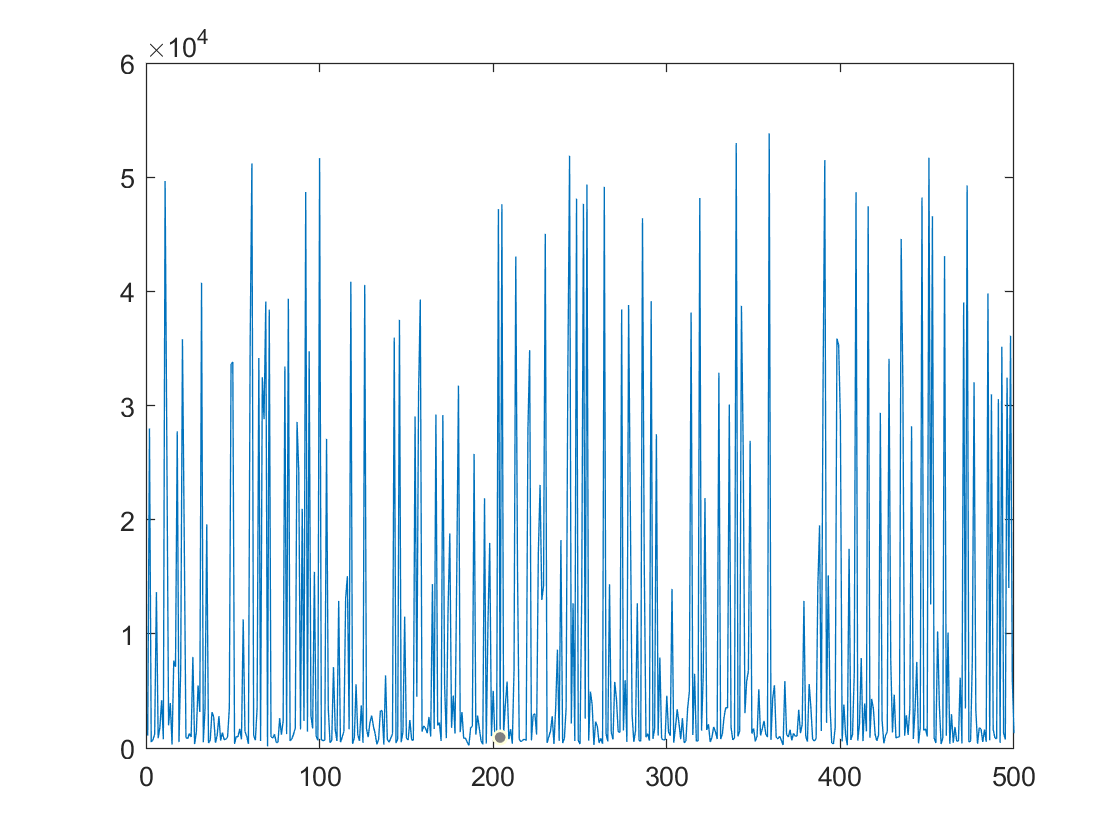

% Plot particle # vs variance
figure
plot(1:n_particle, variance_x);

% xlabel(['Particle number']),ylabel(['Variance']); 


7. Define the deffusion coefficient as D = var/(2*N_kicks). Calculate D.

D = avg_variance/(2*n_kicks)

D = 0.4528

Correction/Solution: Expected value based on expected avg_variance would be 10000/(2*10000) = 0.5. The result was D = 0.4718, so they are pretty close.

`8.. Calculate, approximately, how many pixels - h - will a protein molecule diffusion (in 2D) in a given camera exposure time of 2ms/frame.`

% 100um^2/s * (1 pixel/ 0.4um) * (2 ms / frame)
% 2ms = 2000
h = 100*(1/0.4)*2000

h = 500000

Answer: 500000 pixels.

`Correction: Did not know that protein diffuses according to r^2 = 4Dt.`

`r is the distance diffused (in um in our case.)`

D = 100; % um^2/s, diffusion coefficient.
dx = 0.4; % um/pixel, magnification.
exposureTime = 0.002 % seconds

exposureTime = 0.0020


r = sqrt(4*D*exposureTime); % um. Using r^2 = 4Dt. 
numPixls = r/dx; % result: numPixels = 2.2361